clear all
close all

% prob_map_img = imread('prob_map.png');
% prob_map = prob_map_img(:,:,1);
prob_map = ones(100,100);


[max_x,max_y] = size(prob_map)

max_x = 100

max_y = 100

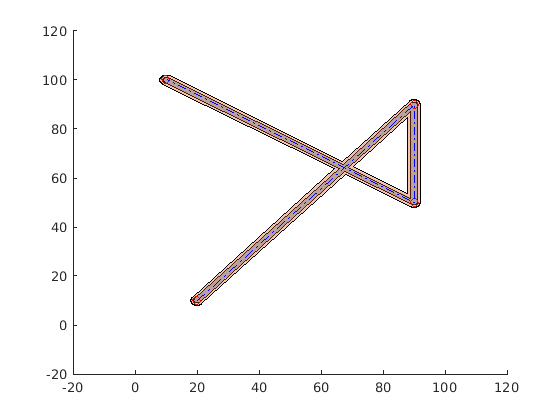


x1 = [max_x*0.2 max_y*0.1];
x2 = [max_x*0.9 max_y*0.9];
x3 = [max_x*0.9 max_y*0.5];
x4 = [max_x*0.1 max_y*1.0];
x_line = [x1;x2;x3;x4];
r = 1;
r_extra_search = 1;

% theta = atan((x2(2)-x1(2))/(x2(1)-x1(1)));
% 
% xConst = r*cos(theta);
% yConst = r*sin(theta);
% 
% x1a = [x1(1) + yConst, x1(2) - xConst];
% x1b = [x1(1) - yConst, x1(2) + xConst];  
% x2a = [x2(1) + yConst, x2(2) - xConst];  
% x2b = [x2(1) - yConst, x2(2) + xConst];  
% 
% poly = polyshape([x1a;x1b;x2b;x2a]);

poly = polybuffer(x_line,'Lines',r);
poly_fat = polybuffer(poly, r_extra_search);

figure
hold on
plot(poly)
plot(poly_fat)
plot(x_line(:,1),x_line(:,2),'ro')
plot(x_line(:,1),x_line(:,2), 'b-.')


[x, y] = meshgrid(1:max_x, 1:max_y);
x = reshape(x,max_x^2,1);
y = reshape(y,max_y^2,1);

[in_fat,on_fat] = inpolygon(x,y,poly_fat.Vertices(:,1),poly_fat.Vertices(:,2));
[in,on] = inpolygon(x,y,poly.Vertices(:,1),poly.Vertices(:,2));

area_covered = zeros(max_x, max_y);
in = reshape(in,max_x,max_y);
found = find(in_fat);
tic
for ind=1:length(found)
    i=found(ind);
    xi = x(i);
    yi = y(i);
    
    if xi+1>max_x || yi+1>max_y  % already naturally capped for -ve values by `inpolygon`
        continue
    end
    
    c2 = [xi+1,yi];
    c3 = [xi,yi+1];
    c4 = [xi+1,yi+1];
    
    
      
    
    truth_arr = [in(c2(1),c2(2)), in(c3(1),c3(2)), in(c4(1),c4(2))] > 0; % c1 is always in `in`
        
    if all(truth_arr)
        area_covered(i) = 1;
    else
        c1 = [xi, yi];
        grid_square = [c1; c2; c4; c3; c1];
        grid_square = polyshape(grid_square);
        polyout = intersect(grid_square,poly);
        area_covered(i) = polyout.area;
    end
end
toc  %0.331823

Elapsed time is 2.908639 seconds.


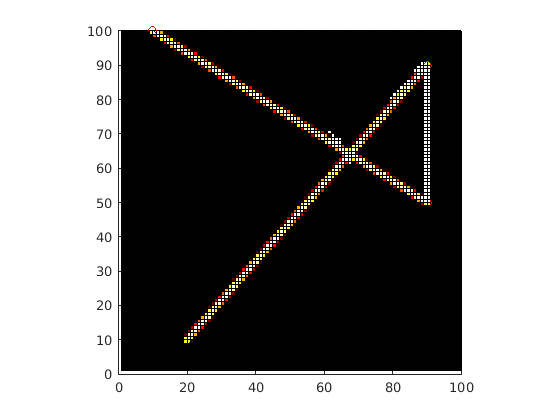


% poly_x = poly.Vertices(:,1);
% poly_y = poly.Vertices(:,2);
% min_poly_x = floor(min(poly_x));
% max_poly_x = floor(max(poly_x));
% min_poly_y = floor(min(poly_y));
% max_poly_y = floor(max(poly_y));
% area_covered = zeros(max_x, max_y);
% in = reshape(in,max_x,max_y);
% tic
% for xi=min_poly_x:max_poly_x
%     if xi<1
%         continue
%     end
%     for yi = min_poly_y:max_poly_y
%         if yi<1
%             continue
%         end
%         c1 = [xi,yi];
%         c2 = [xi+1,yi];
%         c3 = [xi,yi+1];
%         c4 = [xi+1,yi+1];
%         
%         truth_arr = [in(c1(1),c1(2)), in(c2(1),c2(2)), in(c3(1),c3(2)), in(c4(1),c4(2))] > 0;
%         
%         if all(truth_arr)
%             area_covered(xi,yi) = 1;
%         elseif any(truth_arr)
%             grid_square = [c1; c2; c4; c3; c1];
%             grid_square = polyshape(grid_square);
%             polyout = intersect(grid_square,poly);
%             area_covered(xi,yi) = polyout.area;
%         end
%         
%     end
% end
% toc % 0.678069s



figure
%imshow(area_covered)
hold on
surf(area_covered), colormap hot
plot(x_line(:,1),x_line(:,2),'ro')
plot(x_line(:,1),x_line(:,2), 'b-.')
axis equal
xlim([0 max_x])
ylim([0 max_y])


cost = sum(prob_map*area_covered,'all');
disp(cost)

   4.9060e+04



% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% 
% L = linspace(0,2*pi,360);
% % circle = [pos(1)+r*cos(L); pos(2)+r*sin(L)]';
% circle = polyshape(pos(1)+r*cos(L),pos(2)+r*sin(L));
% 
% 
% area_covered = zeros(length(x),1);
% tic
% for i = 1:length(x)
%     c1 = [x(i),y(i)];
%     c2 = [x(i)+1,y(i)];
%     c3 = [x(i),y(i)+1];
%     c4 = [x(i)+1,y(i)+1];
%     
%     dc1 = norm(pos - c1);
%     dc2 = norm(pos - c2);
%     dc3 = norm(pos - c3);
%     dc4 = norm(pos - c4);
%     
%     dists = [dc1 dc2 dc3 dc4]<r;
%     
%     if all(dists)
%         area_covered(i) = 1;
%     elseif any(dists)
%         poly = [c1; c2; c4; c3; c1];
%         poly = polyshape(poly(:,1), poly(:,2));
%         polyout = intersect(poly,circle);
%         area_covered(i) = polyout.area;
%     end
% end
% toc
% 
% area_covered = reshape(area_covered,max_x,max_y);
% 
% imshow(area_covered), colormap hot
% hold on
% xlim([0 max_x])
% ylim([0 max_y])
% 
% disp(pos)
% disp(sum(cast(prob_map,'double').*area_covered,'all'))
